clear

load('spectralGraphPartitioning_circle_3.mat')
%load('spectralGraphPartitioning_circle_4.mat')
%A = Problem.A;
figure

berkD = D;
D1 = berkD(logical(class == 1 ),:)

D1 =     6.2018    1.0000
    7.9172    1.4396
    5.8225    1.6154
    4.4844    1.6716
    6.9034    2.5317
    6.3147    2.7455
    6.3599    3.1458
    3.5487    2.2132
    5.4602    3.4816
    6.5877    4.5910


D2 = berkD(logical(class == 2 ),:)

D2 =    12.7239    1.0000
   10.3079    1.3927
    8.6048    1.6429
   11.4781    2.3327
    9.3674    2.4249
    9.5315    2.8260
   11.4248    3.6954
    9.7327    3.6553
   10.6855    4.3973
   11.7346    5.2816


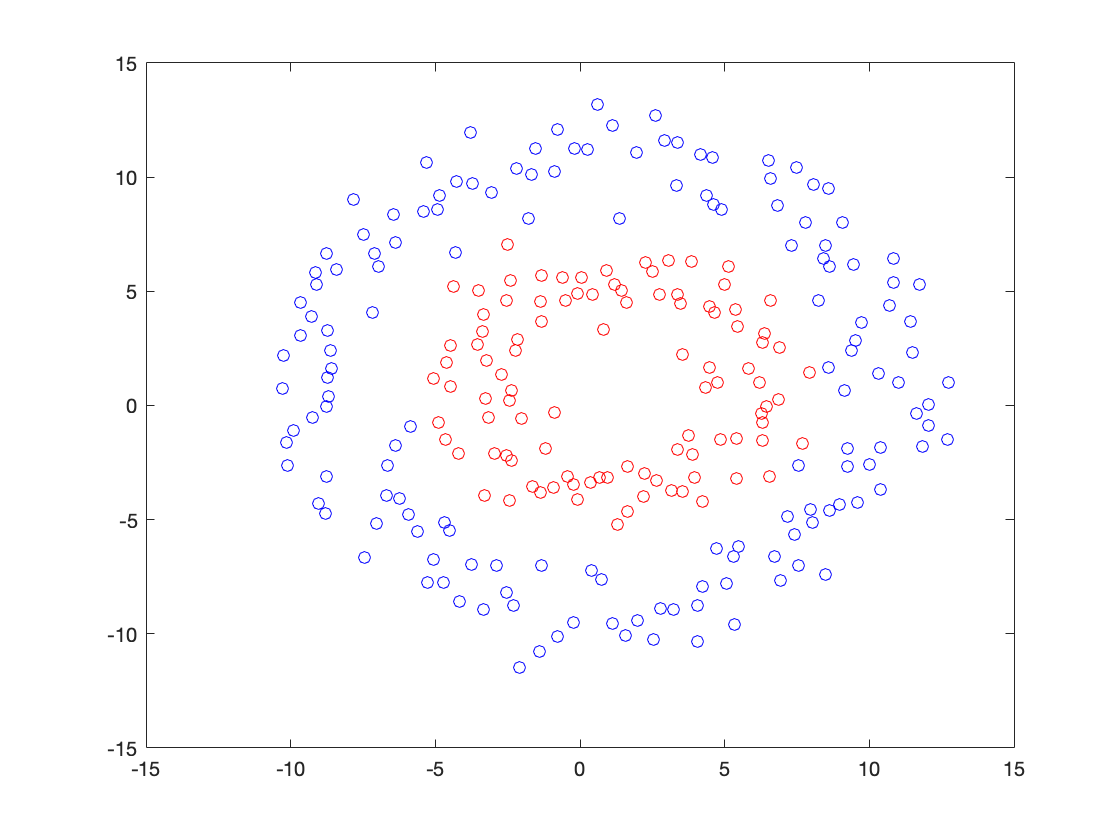

plot(D1(:,1),D1(:,2),'or')
hold on
plot(D2(:,1),D2(:,2),'ob')
hold off

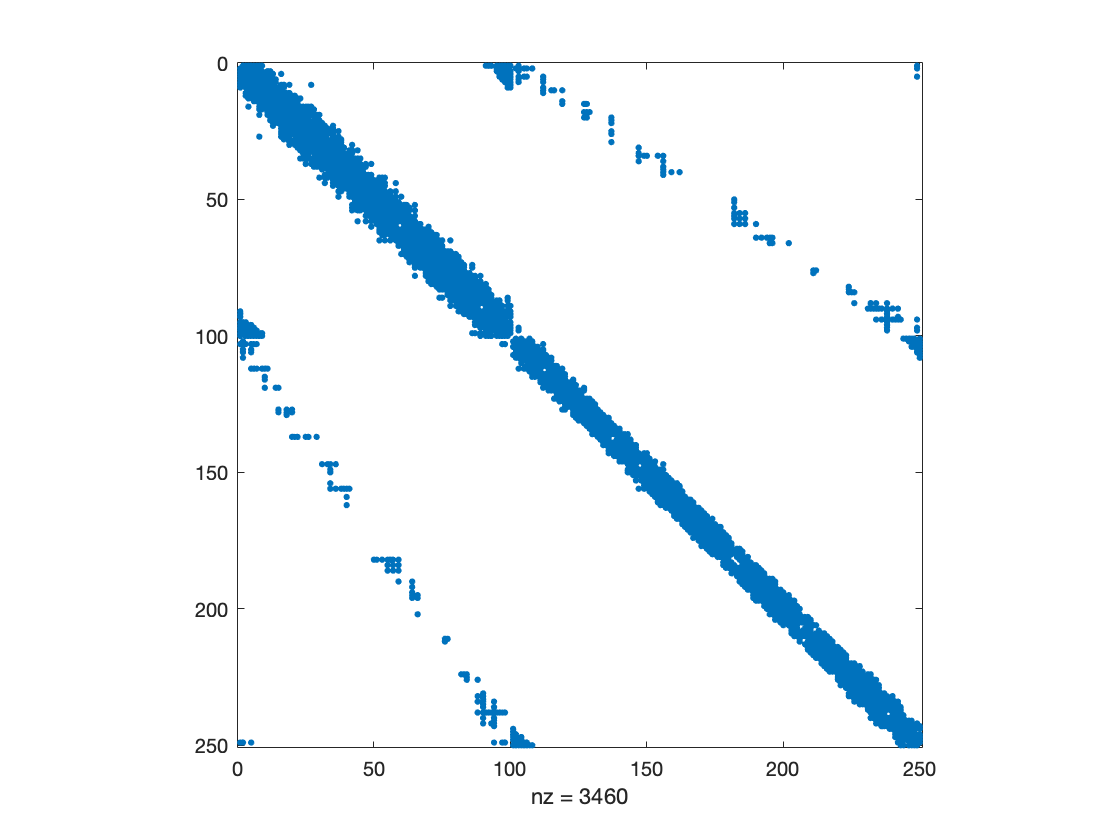


spy(A);

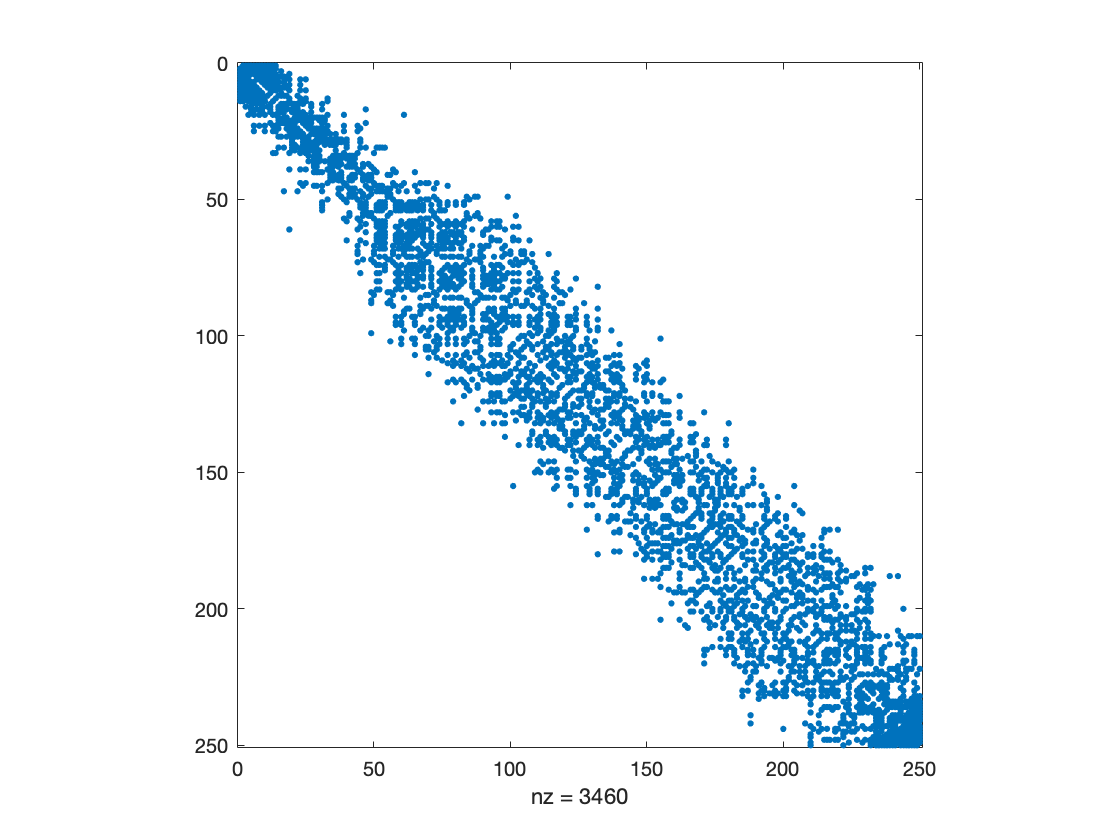

A=double(A);
d = diag(A*A');
D = diag(d);

Dn = diag(d.^-(1/2));
L = full(D-A);
Ln = Dn*L*Dn;
[V,~] = eig(Ln);
Fiedler = V(:,2);

P = speye(length(Fiedler));
[~,p] = sort(Fiedler,'ascend');
P = P(p,:);
Ap = P*A*P';
figure
spy(Ap);

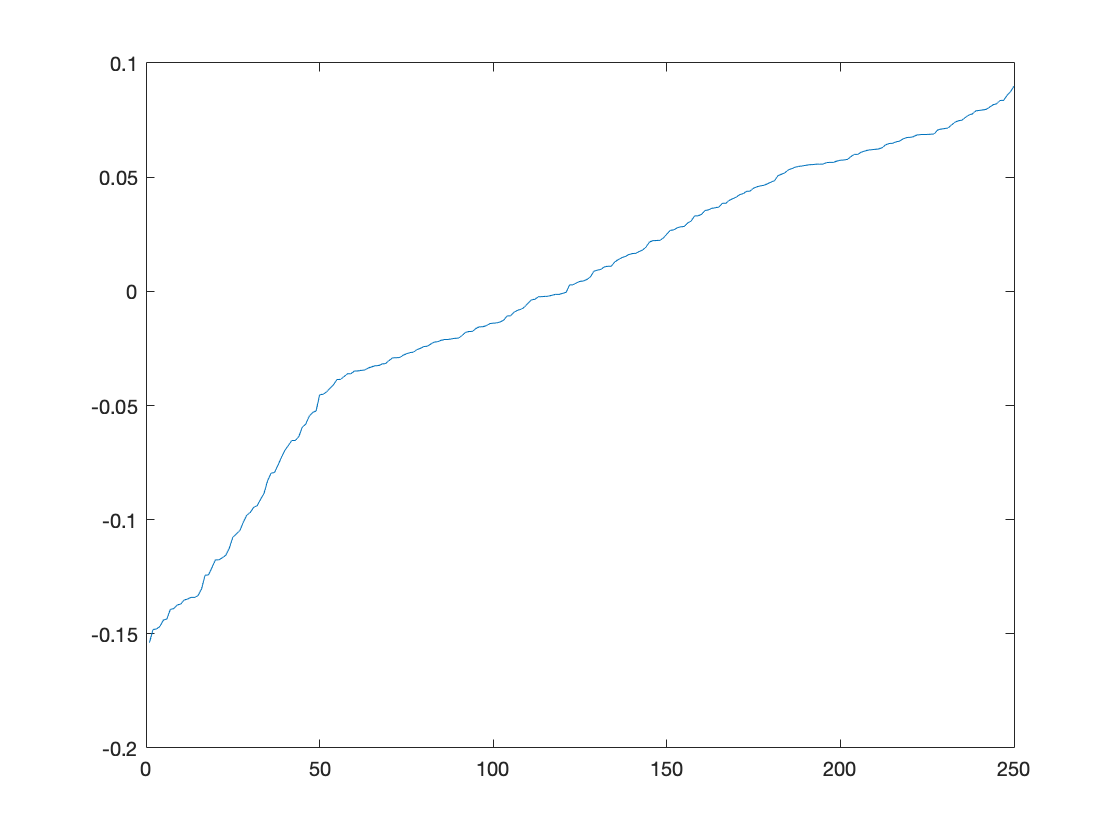


figure
plot(Fiedler(p),'-');

[~,n] = min(abs(Fiedler(p)))

n = 121

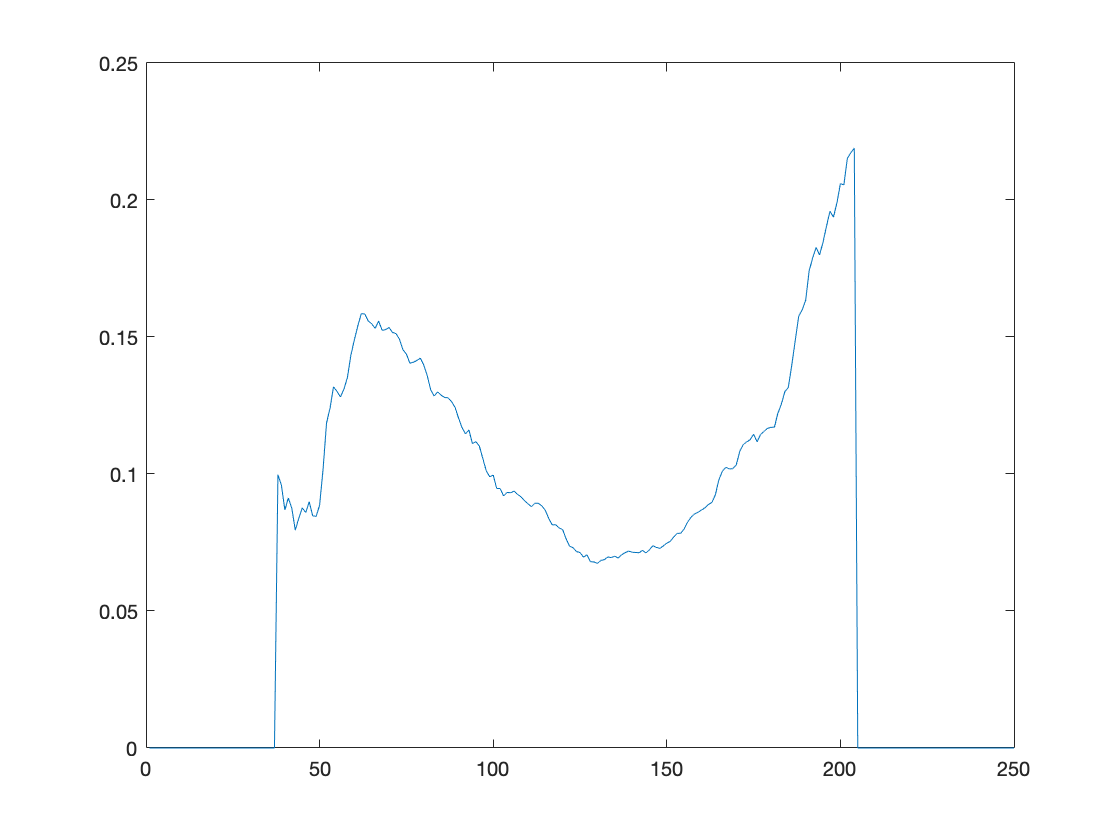

dp = P*d;

% 
% % This part might need a slight refactoring
% % *********************************************
% % Find lowest conductance
cond = zeros(length(dp),1);
interval=3;
% c = 1;
for m=n-(floor(length(dp)/interval)):n+(floor(length(dp)/interval))
%      % We save each cond value with the ind
%      % of that value in the second col.
     cond(m,1) = sum(Ap(1:m,m+1:end),"all") /...
      min(sum(dp(1:m)),sum(dp(m+1:end)));
%     cond(c,2) = nSplit;
%     c = c+1;
end
% 
% 
plot(cond(:,1),'-');

[~,minInd] = min(cond(n-(floor(length(dp)/interval)):n+(floor(length(dp)/interval)),1));
n=minInd+n-(floor(length(dp)/interval))-1%-1 eller inte?

n = 130


% % **********************************************

D3 = berkD(1:n,:)

D3 =     6.2018    1.0000
    7.9172    1.4396
    5.8225    1.6154
    4.4844    1.6716
    6.9034    2.5317
    6.3147    2.7455
    6.3599    3.1458
    3.5487    2.2132
    5.4602    3.4816
    6.5877    4.5910


D4 = berkD(n+1:end,:)

D4 =     4.1505   10.9820
    3.3271    9.6241
    3.3667   11.5152
    2.9181   11.5879
    2.6117   12.6865
    1.9590   11.0769
    1.3805    8.2113
    1.1187   12.2545
    0.6143   13.1912
    0.2458   11.2022


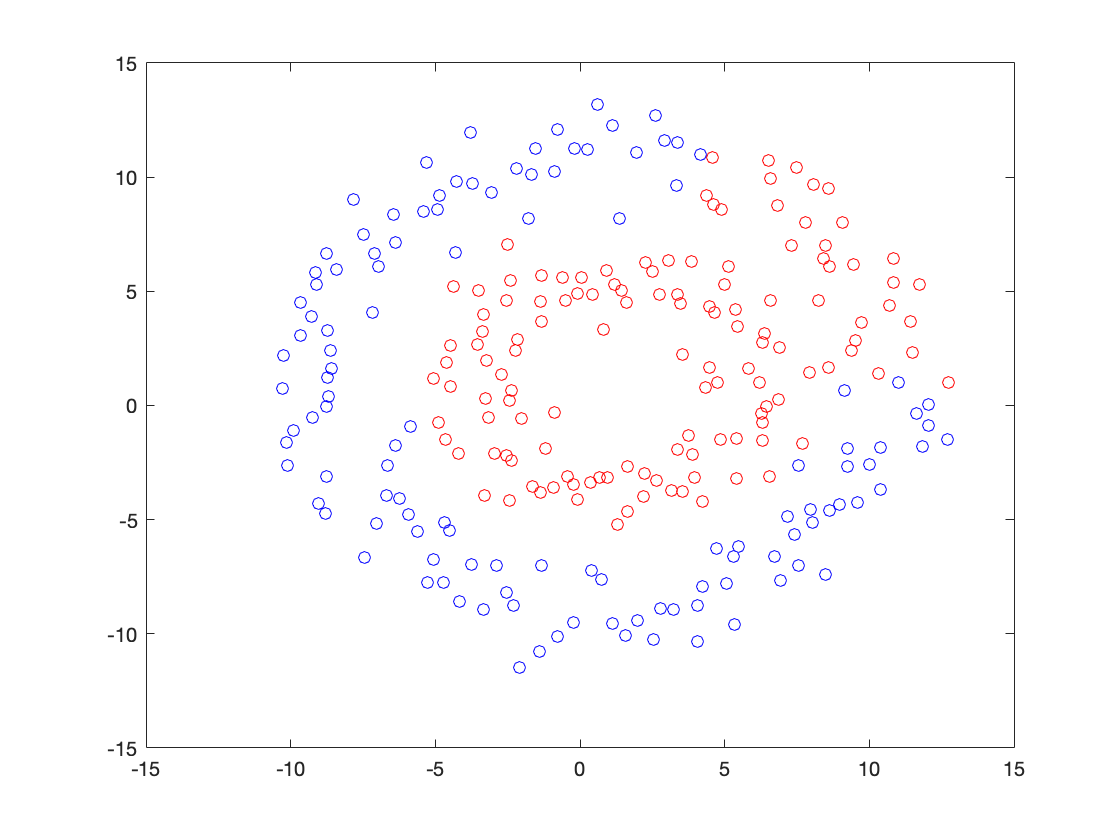

plot(D3(:,1),D3(:,2),'or')
hold on
plot(D4(:,1),D4(:,2),'ob')
hold off

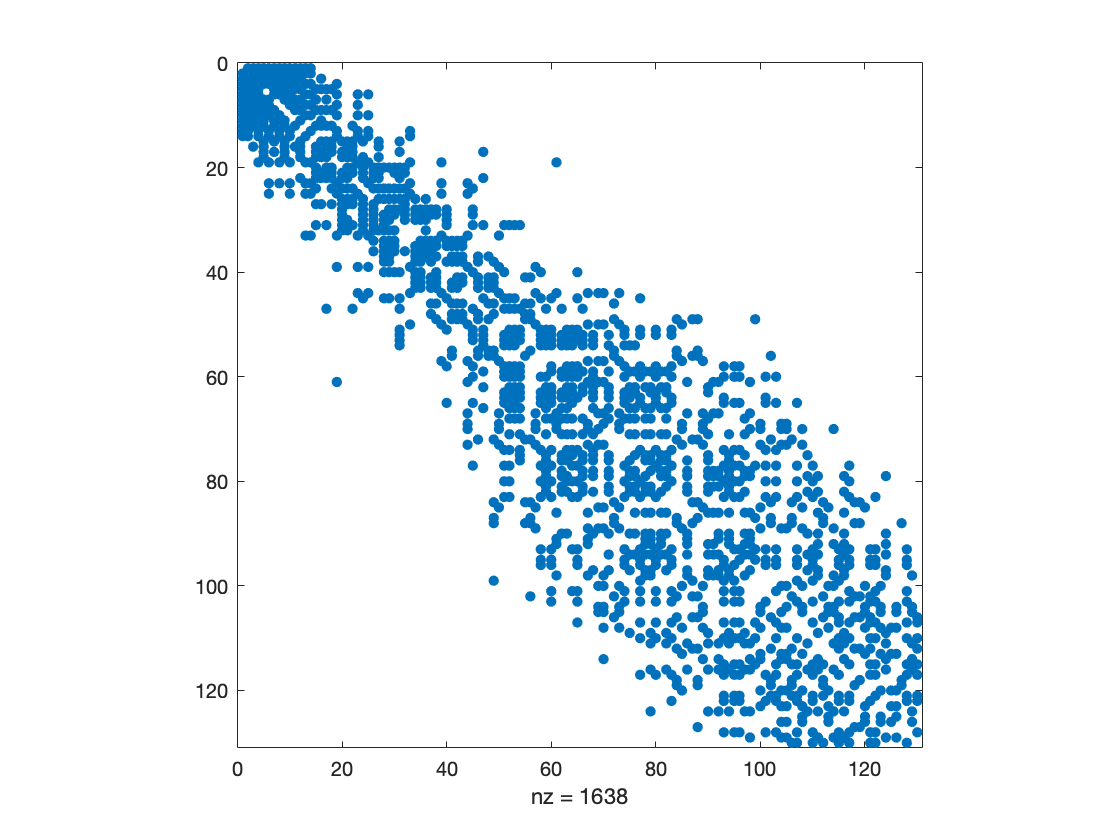


A1 = Ap(1:n,1:n);
A2 = Ap(n+1:end,n+1:end);
spy(A1);

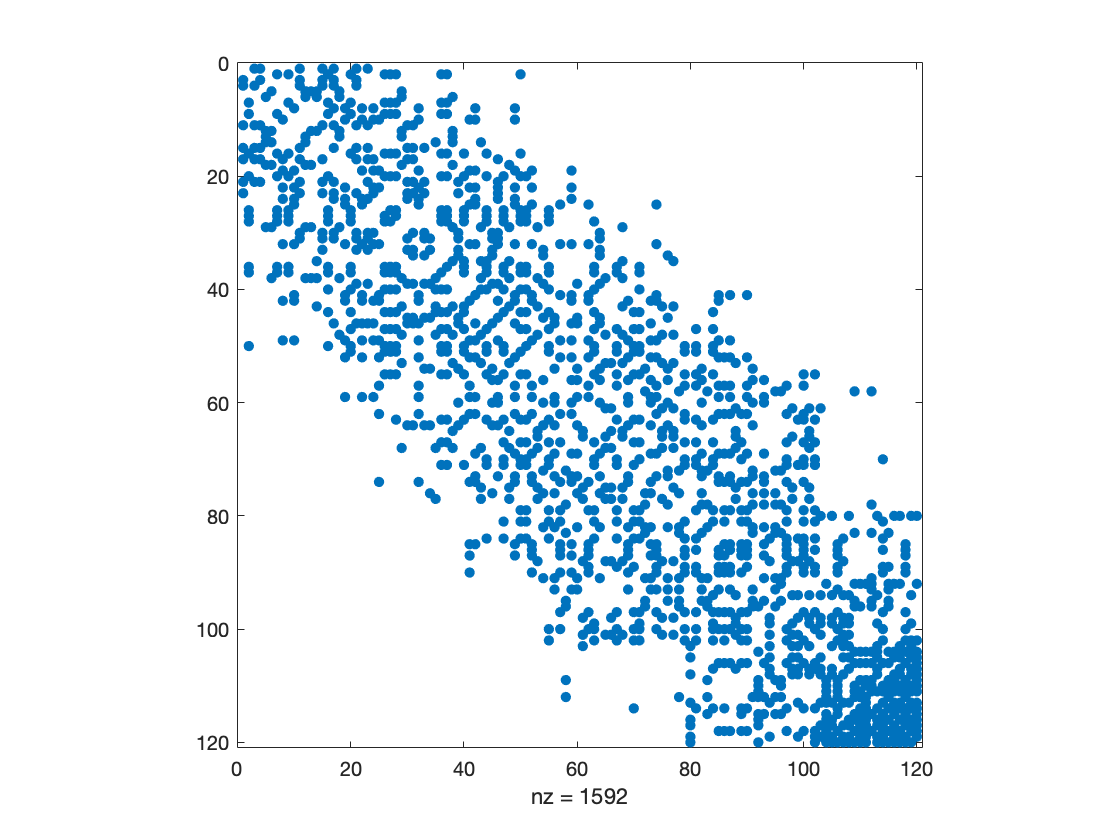

spy(A2);